# 姿勢とライトカーブをstaticに生成 (位置固定)

as a true values for verifying GP_static

clc
clear

### add path for functions

curdir = pwd;
addpath(genpath(strcat(curdir, '/../../yoshimuLibrary/'))); % genpathでサブディレクトリ以下全てのpathを取得
addpath(genpath(strcat(curdir, '/../../hara_functions/')));

### flags

### constants and satellite parameters

const = orbitConst; % for orbital motion
earthVSOP = vsopConst; % for earth orientation

% for time calculation
iau06 = readIAU06;
leapJD = leapS; % load database
fname = "EOP_20_C04_one_file_1962-now.txt";
eopDataAll = readEOP(fname);


model = 2; % 1: flatplate, 2: boxWing
TLE = 1; % 1: read tle, 2: orbit elements べたうち

if model == 1
    objName = 'flatPlate.obj';
    nCompo = 1; % # of object in .obj file
    sat = readSC(objName, nCompo); % satellite shape and optical parameters

    sat.J = diag([10, 15, 20]); % moment of inertia, kgm^2
    sat.m = 50; % mass, kg
    sat.nu = ones(size(sat.faces,1),1) .* 800; %とりあえずベタうち
    sat.nv = ones(size(sat.faces,1),1) .* 800;
    sat.F0 = ones(size(sat.faces,1),1) .* 0.5;
    sat.kappa = 0.0; % thermal emissivity
elseif model == 2
    objName = 'boxWing.obj';
    nCompo = 3; % # of object in .obj file
    sat = readSC(objName, nCompo); % satellite shape and optical parameters

    % sat.J = diag([45, 50, 60]); % moment of inertia, kgm^2
    sat.J = diag([55, 40, 65]);
    sat.m = 100; % mass, kg
    %   optical parameters at wing (manually...)
    % sat.Ca(193:end,:) = 0.1; % absorption
    % sat.Cd(193:end,:) = 0.6; % diffuse
    % sat.Cs(193:end,:) = 0.3; % specular
    sat.Ca = 0.0; % absorption
    sat.Cd = 0.6; % diffuse
    sat.Cs = 0.4; % specular
    sat.nu = ones(size(sat.faces,1),1) .* 800; %とりあえずベタうち
    sat.nv = ones(size(sat.faces,1),1) .* 800;
    sat.F0 = ones(size(sat.faces,1),1) .* 0.5; % [0, 1]
    sat.kappa = 0.0; % thermal emissivity
else
    error('invalid model flag');
end

Reading Object file : boxWing.obj
  % Blender v2.83.1 OBJ File: 'boxWing.blend'
  %www.blender.org
Reading Material file : boxWing.mtl
  % Blender MTL File: 'boxWing.blend'
  % Material Count: 2
Finished Reading Material file
Finished Reading Object file


ans =    242     3


ans =    472     3


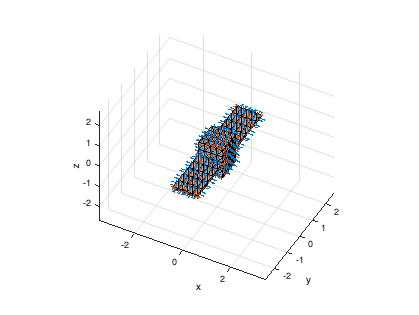

showSC(sat,"Normal","on") % visualize satellite

### initial condition

#### attitude

% qIni = zyx2q(4, -1.3222, 1.4059, 0); % initial quaternion, q(4) is the scalar part
qIni = [0, 0, 0, 1];
% wIni = deg2rad([0.1, -0.4, -0.2]); % initial angular rate, rad/s for asymmetric body
wIni = deg2rad([0.1, -0.1, -0.25]); % for random, まあまあ綺麗に推定できる初期条件...
% wIni = deg2rad([0.05, -0.08, -0.1]); 
% wIni = deg2rad([0.2, 0.15, -0.15]);
% wIni = deg2rad([-0.02, 0.01, 0.05]); % for tleInit
% wIni = deg2rad([-0.01, -0.01, 0.02]);
% wIni = deg2rad([0, 0.3, 0.2]);

xIni = [qIni, wIni];

#### orbit

cowellは解かない

if TLE == 1
    tle = readTLE('JCSAT2_edited.txt', const);
elseif TLE == 2
    a = 42164.91220781728; % [km]
    e = 0.000215800000000; % [-], eccentricity
    inc = 0.000938987137573; % [rad]
    W = 4.918899828139163; % [rad], right ascention of the ascending node
    w = 0.876621287411436; % [rad], argument of perigee
    m = 1.585708419923936; % [rad], mean anomaly at epoch

    tle.oe = [a e inc W w m];
    tle.jd = 2.458535992836310e+06; % [day], Julian day of terestrial time
end

[rIni, vIni] = oe2rv(tle.oe, 1, const); % at inertial frame, km, km/s
rIni = rIni .* 10^3; % m
vIni = vIni .* 10^3; % m/s
jd = tle.jd; % Julian day, day
[yy, mm, dd, hh, m, s] = jd2gc(jd);
utc = datetime([yy, mm, dd, hh, m, s]); % UTC (datetime format)

% initial condition
xIni = [rIni, vIni, qIni, wIni];

### observer location

obsLon = deg2rad(130.216544); % [rad], longitude
obsLat = deg2rad(33.3594649); % [rad], latitude
[obsPosECEF(1), obsPosECEF(2), obsPosECEF(3)] = sph2cart(obsLon, obsLat, const.RE); % [km], observer position @ECEF(Earth Centered Earth Fixed)
obsPosECEF = obsPosECEF .* 10^3; % [m], 1x3 vec

dcmITRF2gcrf = itrf2gcrf(utc, leapJD, iau06, eopDataAll);
qITRF2gcrf = dcm2q(4, dcmITRF2gcrf);
qGCRF2itrf = dcm2q(4, dcmITRF2gcrf');
obsECI = qRotation(4, obsPosECEF, qITRF2gcrf); % [m], observer @ECI, 1x3 vec

### ode

tstep = 1;
tspan = 0:tstep:60*10;

options = odeset('RelTol',1e-9,'AbsTol',1e-9);
[t_, x_] = ode89(@(t,x)eomAttiOrb_h(t, x, const, earthVSOP, sat, jd), tspan, xIni, options);

### data handling

jdHistory = tle.jd + s2day(t_); % time history in Julian day
[yy, mm, dd, hh, m, s] = jd2gc(jdHistory);
utc = datetime([yy, mm, dd, hh, m, s]); % UTC (datetime format)
for ii = 1:length(t_)
    dcmITRF2gcrf = itrf2gcrf(utc(ii), leapJD, iau06, eopDataAll); % International Terrestrial Reference Frame to Geocentric Celestial Reference Frame(inertial frame)
    qITRF2gcrf(ii, :) = dcm2q(4, dcmITRF2gcrf);
end

r = x_(:, 1:3); % [m], position @ i-frame
v = x_(:, 4:6); % [m/s], velocity @ i-frame
q = x_(:,7:10); % quaternion w.r.t. inertial frame
w = x_(:,11:13); % [rad/s], angular rate w.r.t. inertial frame

tmp = q2zyx(4, q);
phi = tmp(:,1);
theta = tmp(:,2);
psi = tmp(:,3);

### Sun position and Observer positions

sunPosI = sun(jdHistory, const, earthVSOP);
sunPosI = sunPosI .* 10^3; % m
sunRel = sunPosI - r; % relative vec from sat to sun @inertial frame, nx3, m
sunRel(1,:)

ans = 1.0e+11 *

    1.3097   -0.6315   -0.2736


sunPosB = qRotation(4, normRow(sunRel), q);% sun unit directional vectors @body-fixed frame, nx3

obsECI = qRotation(4, repmat(obsPosECEF,length(jdHistory),1), qITRF2gcrf); % observer position @ECI, nx3 m
obsRel = obsECI - r; % relative vec from sat to observer @inertial frame, nx3, m
obsRel(1,:)

ans = 1.0e+07 *

   -0.7345   -3.6391    0.3484


obsB = qRotation(4, normRow(obsRel), q); % relative observer directional vectors@inertial frame, nx3,

### generate light curves

nu = shadow(r./10^3, sunPosI./10^3, const.RS, const.RE); % calc Earth's shadow
[mApp, ~] = lc(sat, 4, q, r, obsECI, sunPosI, nu, 'AS'); % tspanx1

### show figs

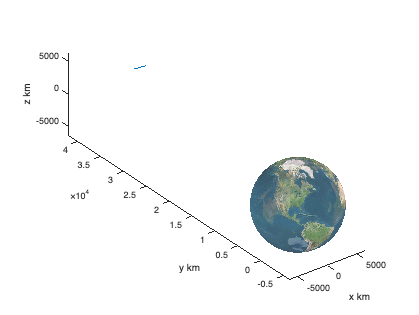

figure
plot3(r(:,1)./1000, r(:,2)./1000,r(:,3)./1000)
hold on;
tmp = gmst(jdHistory(end));
drawEarth(tmp, 0.6, const);
hold on;
plot3(obsECI(:,1)./1000, obsECI(:,2)./1000,obsECI(:,3)./1000,'r')
% hold on;
% plot3(sunPosI(:,1)./1000, sunPosI(:,2)./1000, sunPosI(:,3)./1000, 'g')
hold off;
xlabel('x km'), ylabel('y km'), zlabel('z km')
axis equal

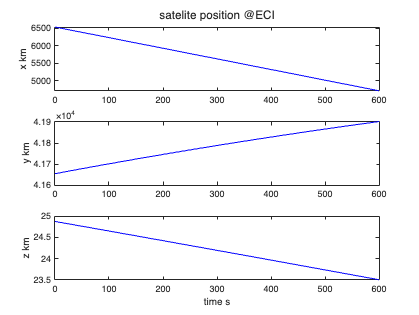


% figure
% plot3(sunPosI(:,1)./1000, sunPosI(:,2)./1000, sunPosI(:,3)./1000, 'g')

% satelite position
figure
tile = tiledlayout(3,1, 'TileSpacing','Compact');
nexttile
plot(t_, r(:,1)./1000, 'b');
ylabel("x km");
nexttile
plot(t_, r(:,2)./1000, 'b');
ylabel("y km");
nexttile
plot(t_, r(:,3)./1000, 'b');
ylabel("z km");
xlabel("time s")
title(tile, "satelite position @ECI")

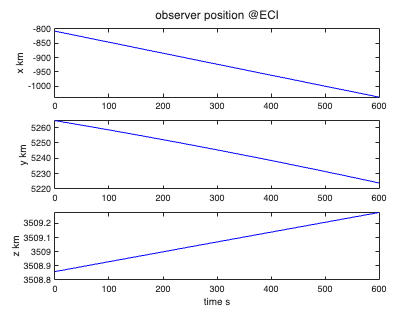


% observer position
figure
tile = tiledlayout(3,1, 'TileSpacing','Compact');
nexttile
plot(t_, obsECI(:,1)./1000, 'b');
ylabel("x km");
nexttile
plot(t_, obsECI(:,2)./1000, 'b');
ylabel("y km");
nexttile
plot(t_, obsECI(:,3)./1000, 'b');
ylabel("z km");
xlabel("time s")
title(tile, "observer position @ECI")

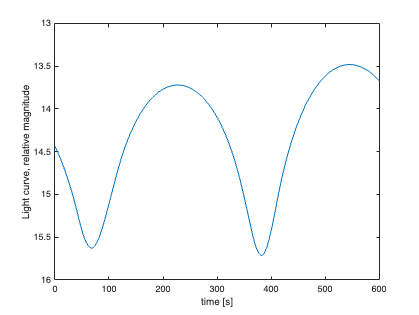



figure
plot(t_, mApp)
xlabel('time [s]'), ylabel('Light curve, relative magnitude')
set(gca, 'YDir', 'reverse')


%% attitude
figure % quaternion
tFig = tiledlayout(4,1), nexttile

tFig =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [4 1]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


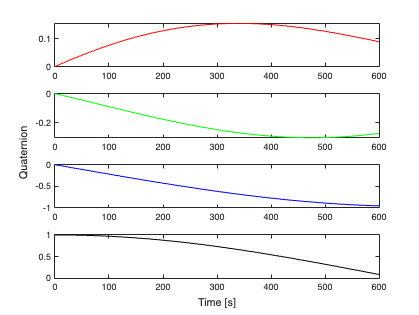

plot(t_,q(:,1),'r'), nexttile
plot(t_,q(:,2),'g'), nexttile
plot(t_,q(:,3),'b'), nexttile
plot(t_,q(:,4),'k')
xlabel(tFig, 'Time [s]')
ylabel(tFig, 'Quaternion ')

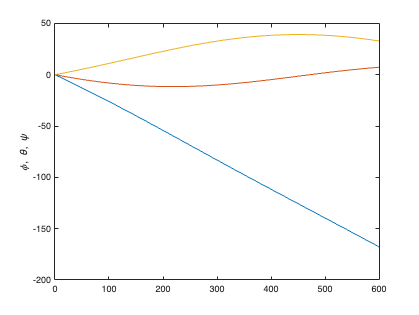


figure % attitude angle
plot(t_, rad2deg(phi))
hold on
plot(t_, rad2deg(theta))
plot(t_, rad2deg(psi))
ylabel('\phi, \theta, \psi')

### save data

fName = strcat(objName(1:end-4), "_lcAtti_onOrbit");
saveName = strcat(fName, '.mat');
save(saveName, 't_', 'mApp', 'q', 'phi', 'theta', 'psi', 'w', 'sat', 'r', 'v', 'obsECI', 'sunPosI', 'jdHistory')